# Ejercicio 2

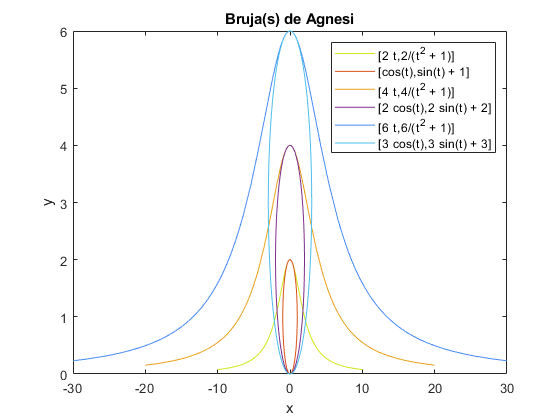

clear; clc; clf;

syms t

crear = input("Crear bruja? 1 = Sí, 0 = No\n");
if (crear ==1)
    a = input("Dame 'CT'\n");
end

while (crear == 1)

    xB = 2 * a * t;
    yB = (2 * a) / (1 + t^2);
    
    % xB = 2 * a * tan(t);
    % yB = 2 * a * cos(t).^2;
    
    R = rand();
    G = rand();
    B = rand();

    fplot(xB,yB, "Color", [R G B])
    legend("-DynamicLegend")
    legend("show")
    xlabel("x")
    ylabel("y")
    
    hold on

    % yL = 2 * a;

    % fplot(yL, "Color", "r")
    
    title("Bruja(s) de Agnesi")
    
    circulo = input("Graficar círculo? 1 = Sí, 0 = No\n");
    if (circulo == 1)
        xC = a * cos(t);
        yC = a * sin(t) + a;
        fplot(xC, yC)
    end

    crear = input("Seguir creando brujas? 1 = Sí, 0 = No\n");
    if (crear == 1)
        a = input("Dame 'CT'\n");
    end
    
end

saveas(gcf, "brujas.png");

% Para encontrar las ecuaciones paramétricas se tiene que 'y' es igual a 'a' más la longitud de CD, suponiendo que D es igual a 'y' y se traza un triángulo de DCA, por lo que DCA es igual a 2*theta y CD es igual a a*cos(2*theta). Por lo que se tienen 'y = a+a*cos(2*theta)' y 'x = 2*a*tan(theta)'. Expandiendo y usando leyes trigonométricas nos da lo obtenido (ver comentarios en líneas 17 y 18, para fines estéticos en la graficación se usaron las ecuaciones paramétricas de -∞ a ∞).

%Para encontrar la ecuación cartesiana, se despeja t de 'x' o 'y' y se sustituye en la otra ecuación. 

syms a t x y
ecuacionesParametricas = [x == 2 * a * t; y == (2 * a) / (1 + t^2)]

$$ecuacionesParametricas = \left(\begin{array}{c} x=2\,a\,t\\ y=\frac{2\,a}{t^{2}+1} \end{array}\right)$$

ecuacionCartesiana = subs(ecuacionesParametricas(2), t, rhs(isolate(ecuacionesParametricas(1), t)))

$$ecuacionCartesiana = y=\frac{2\,a}{\frac{x^{2}}{4\,a^{2}}+1}$$